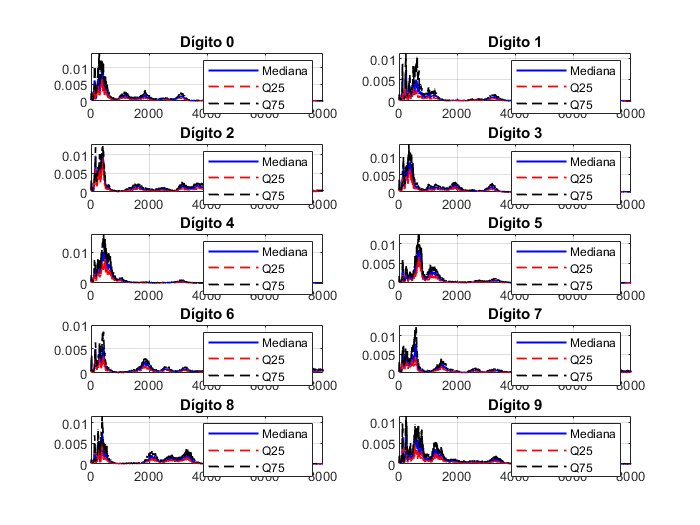

load('projeto.mat'); 
load('table.mat');

T.Coeficientes_Fourier = cell(height(T), 1);
espectros_por_digito = cell(10, 1);

for i = 1:height(T)
    digito = T.("Dígito")(i) + 1;  % Ajuste para índice do MATLAB
    fs = T.("Taxa Amostragem")(i);  % Taxa de amostragem
    sinal = T.Sinal{i};

    % Tamanho do sinal
    N = length(sinal);

    % Calcula a FFT
    coeficientes = fft(sinal) / N;  % Normaliza pelo número de amostras

    % Armazena os coeficientes na tabela
    T.Coeficientes_Fourier{i} = coeficientes; 

    % Espectro de amplitude para frequências positivas
    espectro = abs(coeficientes(1:floor(N/2)+1)); 

    % Frequências positivas correspondentes
    frequencias_positivas = (0:floor(N/2)) * (fs / N);

    % Armazena o espectro para o dígito correspondente
    espectros_por_digito{digito} = [espectros_por_digito{digito} espectro];
end


% Cálculo dos quartis para cada dígito
mediana_espectros = cell(10, 1);
Q25_espectros = cell(10, 1);
Q75_espectros = cell(10, 1);

for d = 1:10
    if ~isempty(espectros_por_digito{d})
        mediana_espectros{d} = median(espectros_por_digito{d}', 1);
        Q25_espectros{d} = quantile(espectros_por_digito{d}', 0.25, 1);
        Q75_espectros{d} = quantile(espectros_por_digito{d}', 0.75, 1);
    end
end

% Plotar os gráficos
figure;
for d = 1:10
    subplot(5, 2, d);  % Criar subplots para os 10 dígitos
    if ~isempty(mediana_espectros{d})
        plot(frequencias_positivas, mediana_espectros{d}, 'b', 'LineWidth', 1.2); hold on;
        plot(frequencias_positivas, Q25_espectros{d}, 'r--', 'LineWidth', 1);
        plot(frequencias_positivas, Q75_espectros{d}, 'k--', 'LineWidth', 1);
        title(sprintf('Dígito %d', d-1));
        xlim([0 8000]);  % Limite de frequência para voz
        legend('Mediana', 'Q25', 'Q75');
        grid on;
    end
end